# Course 3. Example 3.5: D-LQR

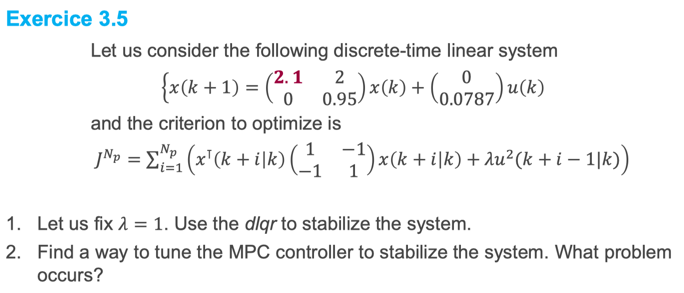

### Initialisation

clear;
close all;
clc;

#### **Q1: Model prediction**

% System definition
A=[2.1 2 ;0 0.95];
B=[0; 0.0787];
nx=size(A,2);
nu=size(B,2);

% Model prediction
Np=10;
F=zeros(Np*nx,nx);
H=zeros(Np*nx,Np*nu);

for i=1:Np
    F(nx*(i-1)+1:nx*i,:)=A^i ;
    for j=1:i
        H(nx*(i-1)+1:nx*i,nu*(j-1)+1:nu*j)=A^(i-j)*B;
    end
end


#### Q2: Feedback Control

% Objective function
lambda=0.1;

Q = [1 -1; -1 1];
% Warning: Your Hessian is not symmetric. 
% Resetting H=(H+H')/2.
R = lambda;

Qx=zeros(nx*Np);
Ru=zeros(nu*Np);

for i =1:Np
    Qx(nx*(i-1)+1:nx*i,nx*(i-1)+1:nx*i)=Q;
    Ru(nu*(i-1)+1:nu*i,nu*(i-1)+1:nu*i)=R;
end

#### Q3: Optimal feedback (off-line computation)

First=zeros(nu,nu*Np);
First(nu,nu)=eye(nu);
K_Np=First*(H'*Qx*H+Ru)^(-1)*H'*Qx*F;

#### Q3: Closed-loop implementation: MPC approach

Use quadprog to determine the optimal input sequence using U(K|k) as the optimization variable.

Nsimu=10;
xinit=[1;1];
xk=xinit;
H_quad = 2*(H'*Qx*H + Ru); % indenpendent from k
X1 = [];
for i=1:Nsimu
    X1 = [X1 xk];
    f_quad = 2*H'*Qx*F*xk;
    [Uopt,Jopt] = quadprog(H_quad,f_quad);
    uk=First*Uopt; %optimal control
    xkp1=A*xk+B*uk;
    xk=xkp1;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



X1

X1 =     1.0000    4.1000    3.7662    2.6193    1.5801    0.8614    0.4295    0.1946    0.0779    0.0252
    1.0000   -2.4219   -2.6448   -1.9602   -1.2284   -0.6898   -0.3536   -0.1654   -0.0692   -0.0244


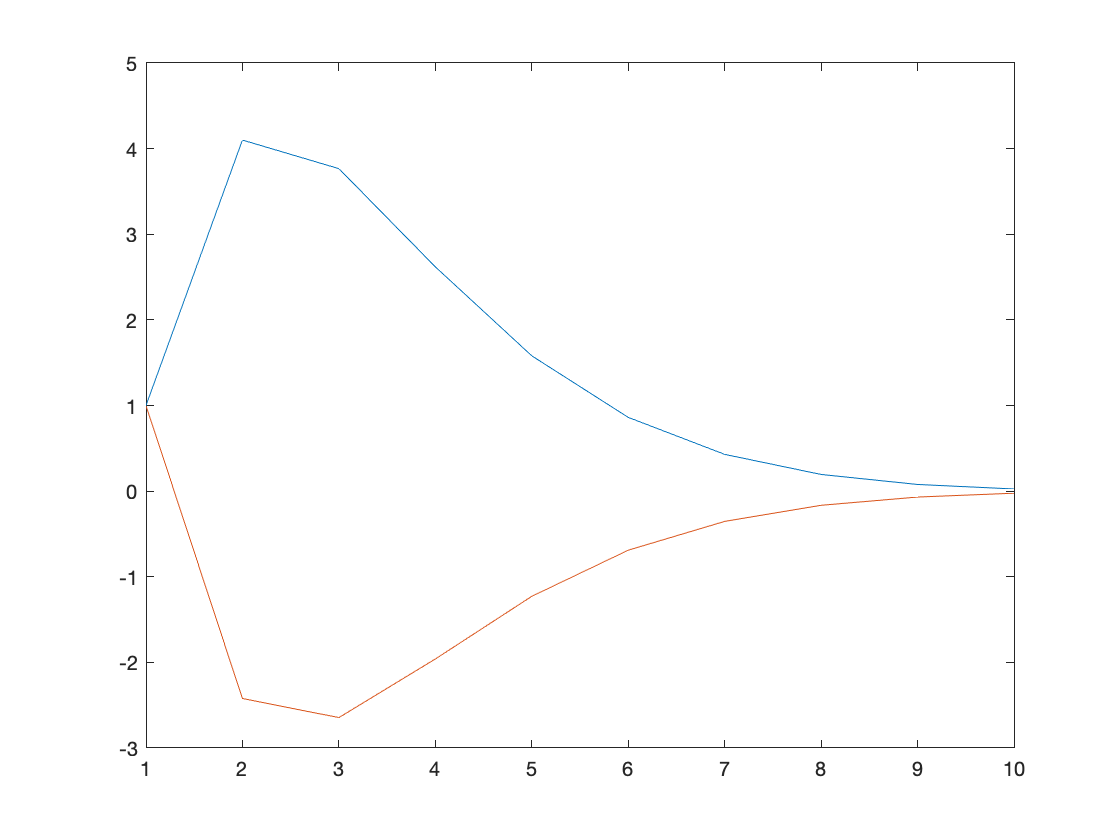

plot(1:Nsimu,X1);

#### Analysis of the closed-loop system

eigenvalues=eig(A-B*K_Np);
module1 = norm(eigenvalues(1),1)

module1 = 0.5139

#### Q4： Try another configuration for the optimization: D-LQR regulation

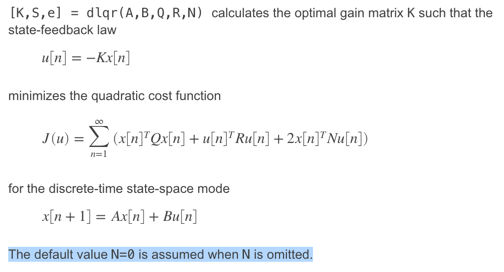

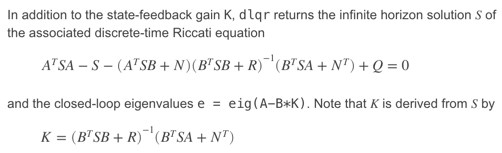

lambda = 0.1;
R = lambda;
% A, B, Q, R are the same
% defaut value N = 0, since there is no term of type x(k)*u(k)
[Klqr,P,eigenvals] = dlqr(A,B,Q,R);


#### Analysis

Eigenvaluesdlqr=eig(A-B*Klqr)

Eigenvaluesdlqr =    0.4913 + 0.1501i
   0.4913 - 0.1501i


EigenvaluesMPC_Np=eig(A-B*K_Np)

EigenvaluesMPC_Np =    0.4915 + 0.1501i
   0.4915 - 0.1501i


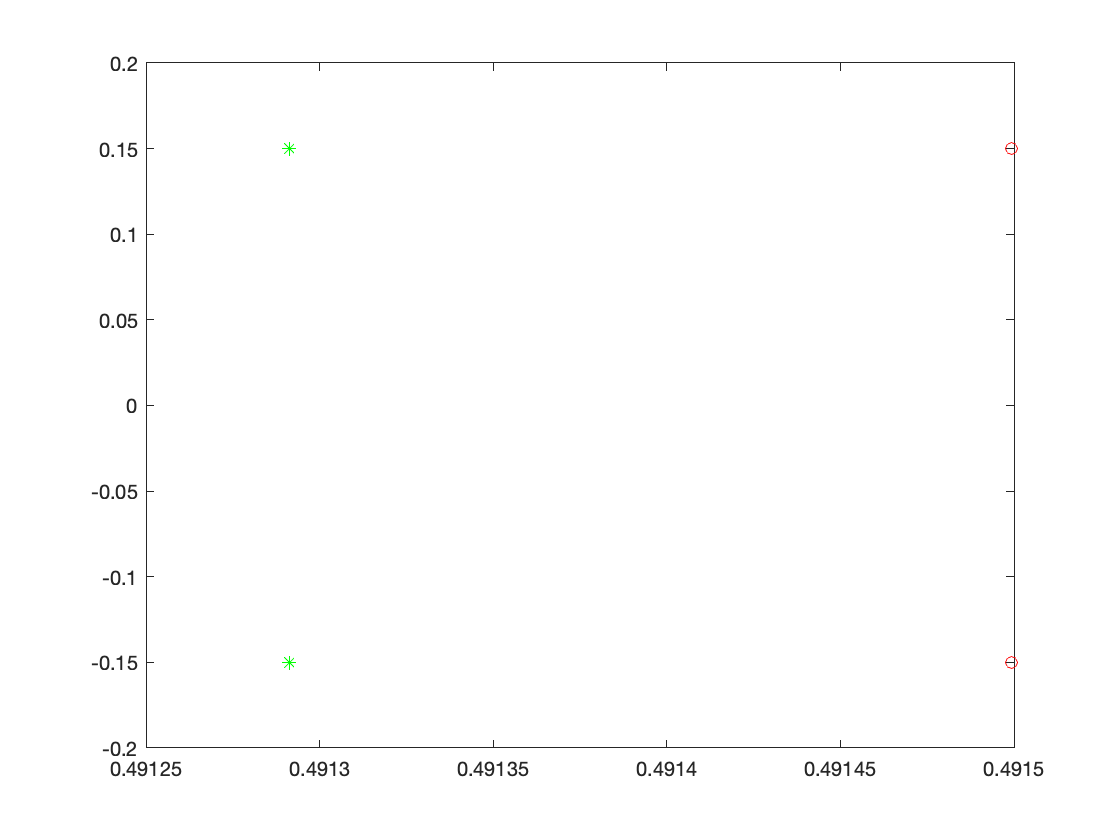


EigdlqrReal=real(Eigenvaluesdlqr);
EigdlqrImag=imag(Eigenvaluesdlqr);
EigMPC_NpReal=real(EigenvaluesMPC_Np);
EigMPC_NpImag=imag(EigenvaluesMPC_Np);

figure
plot(EigdlqrReal,EigdlqrImag,'g*')
hold on
plot(EigMPC_NpReal,EigMPC_NpImag,'ro')

Np 和收敛速度

**Q2: The problem occurs: sensibility regrading lambda, H**

lambda:=> Ru

K_Np=First***(H'*Qx*H+Ru)^(-1){sensible factor}***H'*Qx*F;